% =========================================================================
%                       Manuel Santos   2019231352
% =========================================================================

clear; close all; clc;

load("AT&T.mat");

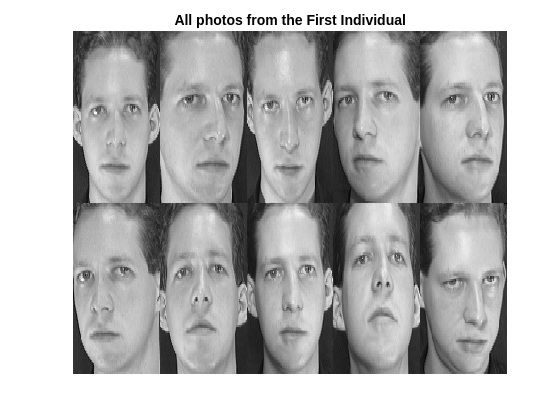

% Show Faces of First Individual
Faces_One = zeros(h_ATeT*2,w_ATeT*5);
count = 1;
for i=1:2
    for j=1:5
        Faces_One(1+(i-1)*h_ATeT:i*h_ATeT,1+(j-1)*w_ATeT:j*w_ATeT) = reshape(allFaces_ATeT(:,count),h_ATeT,w_ATeT);
        count = count + 1;
    end
end
figure
imagesc(Faces_One),colormap('gray');
axis off; title("All photos from the First Individual")

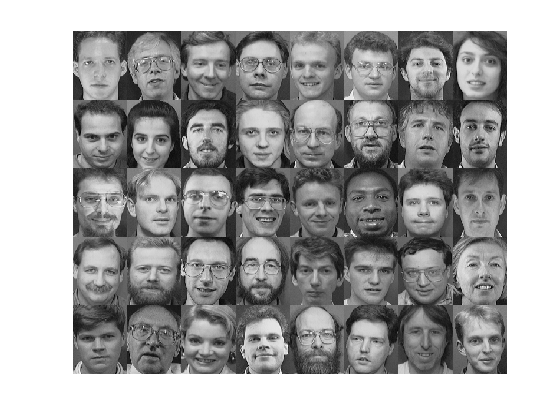

% Show First face of All Individuals
Face_One_All = zeros(h_ATeT*5,w_ATeT*8);
count = 1;
for i=1:5
    for j=1:8
        Face_One_All(1+(i-1)*h_ATeT:i*h_ATeT,1+(j-1)*w_ATeT:j*w_ATeT) = reshape(allFaces_ATeT(:,(count-1)*10 + 1),h_ATeT,w_ATeT);
        count = count + 1;
    end
end
figure
imagesc(Face_One_All),colormap('gray');
axis off; title("First photo from All Individuals")

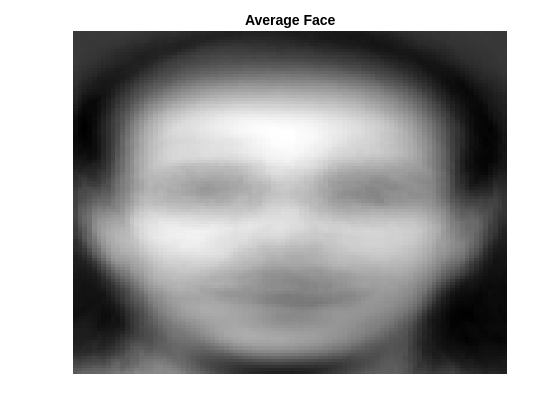

% Select train and test faces
numTrain = 35; % 36 to 40 are for tests
trainFaces = allFaces_ATeT(:,1:numPhotosPerSubject_ATeT*numTrain);
testFaces = allFaces_ATeT(:,numPhotosPerSubject_ATeT*numTrain+1:end);

% Calculate average face
avgFace = mean(trainFaces,2);

% Plot average face
figure
imagesc(reshape(avgFace(:),h_ATeT,w_ATeT));
colormap("gray"); axis off; title("Average Face");

% Calculate SVD
X = double(trainFaces)-avgFace.*ones(size(trainFaces));
[U,S,V] = svd(X,'econ');

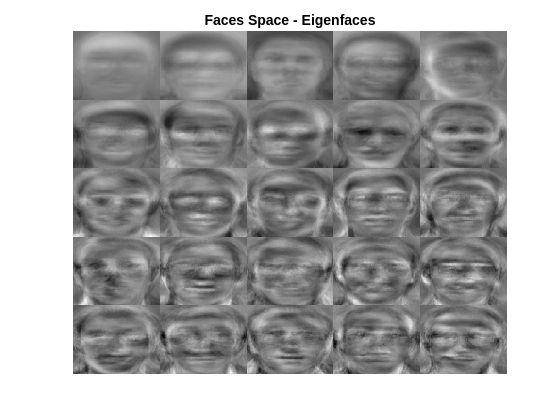

% Show Eigenfaces
sizeTile = 5;
EigenFaces = zeros(h_ATeT*sizeTile,w_ATeT*sizeTile);
count = 1;
for i=1:sizeTile
    for j=1:sizeTile
        EigenFaces(1+(i-1)*h_ATeT:i*h_ATeT,1+(j-1)*w_ATeT:j*w_ATeT) = reshape(U(:,count),h_ATeT,w_ATeT);
        count = count + 1;
    end
end

% Plot Eigenfaces
figure
imagesc(EigenFaces),colormap('gray');
axis off; 
title("Faces Space - Eigenfaces");

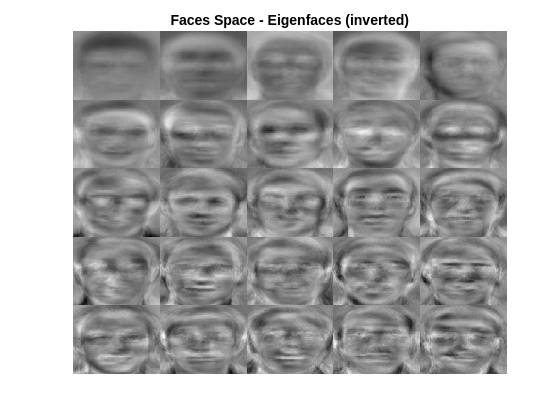


figure
imagesc(EigenFaces.*-1),colormap('gray');
axis off; title("Faces Space - Eigenfaces (inverted)");

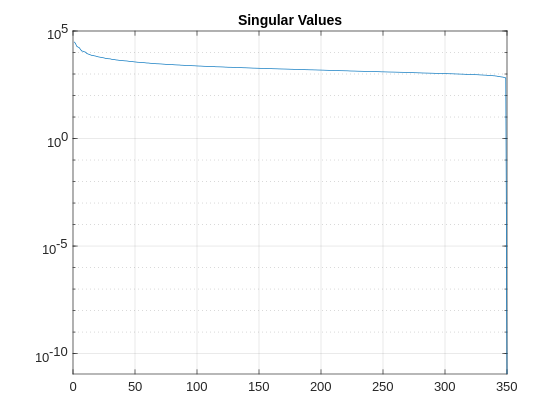

% Show singular values
figure
semilogy(diag(S))
grid on; title("Singular Values");

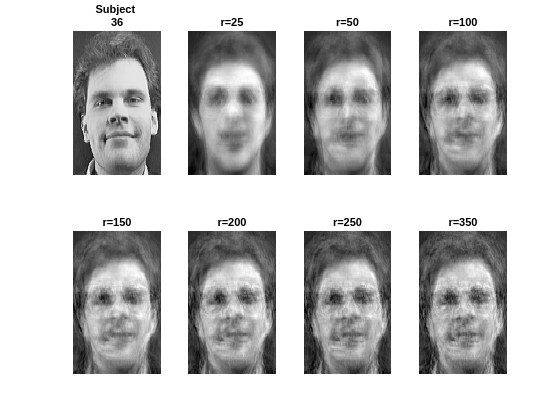

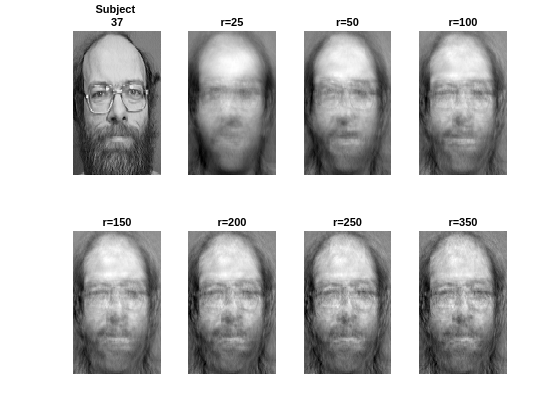

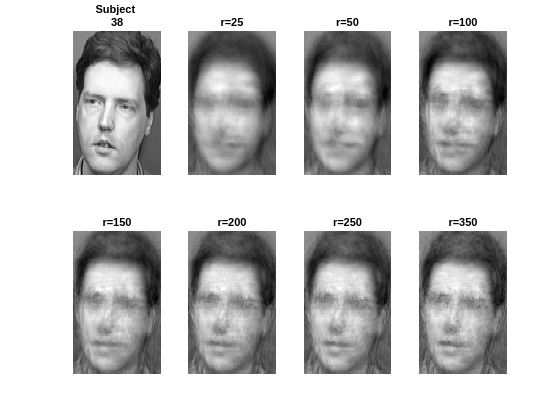

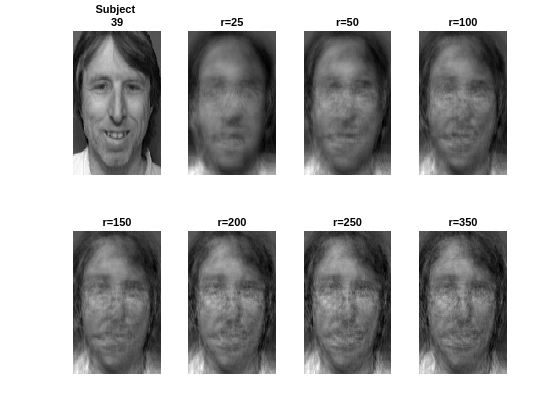

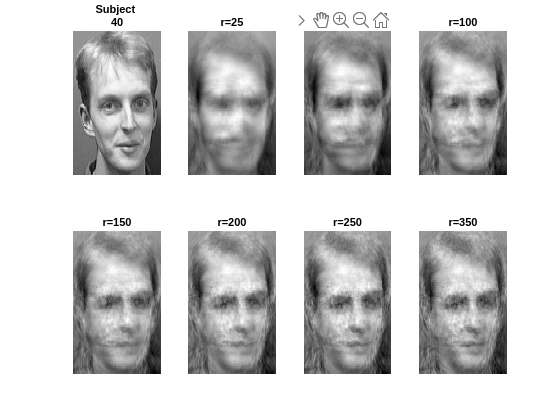

% Reconstruct unseen test face from eigenfaces
 for i = [0 10*1 10*2 10*3 10*4]
    figure
    subplot(2,4,1);
    imagesc(reshape(testFaces(:,i+1),h_ATeT,w_ATeT));
    colormap("gray"); axis off;
    title(["Subject " num2str(36+(i/10))])
    
    count = 1;
    testFaceMS = double(testFaces(:,i+1)) - avgFace;
    for r=[25 50 100 150 200 250 350]
        count = count + 1;
        subplot(2,4,count);
        reconFace = avgFace + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
        imagesc(reshape(reconFace,h_ATeT,w_ATeT));
        colormap("gray"); axis off;
        title(['r=' num2str(r,'%d')]);
    end
 end